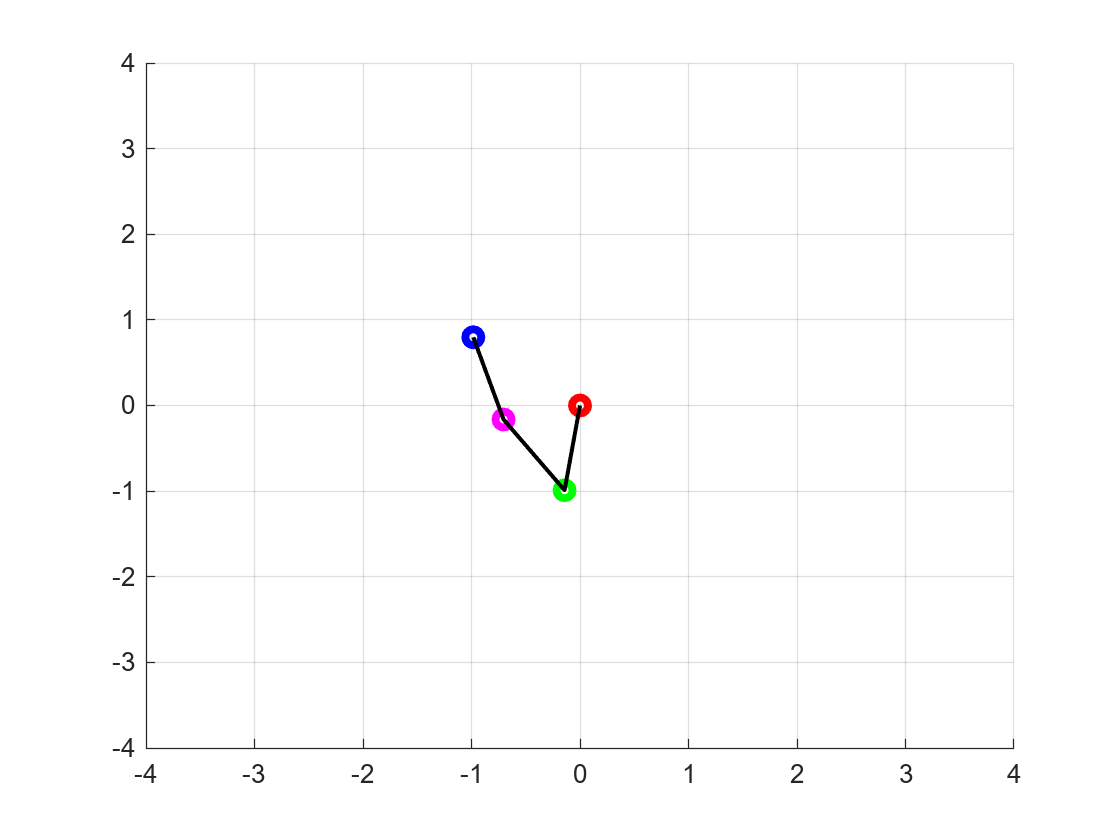

clc; close all; clear;
 
format compact;
set(0, 'DefaultFigureWindowStyle','docked')

% Create a figure for plotting
figure(1); hold on; grid on;
axis([-4 4 -4 4]);

% Initial joint angles (3R robot)
Q = [0; 0; 0];
% Initial joint velocities
dQ = [0; 0; 0];
% External torques
T = [0; 0; 0];
% Time
t = 0;
% Time step
dt = 0.01;



while(1)
    % Compute trigonometric functions of joint angles
     c1 = cos(Q(1));
     s1 = sin(Q(1));
     c2 = cos(Q(2));
     s2 = sin(Q(2));
     s3 = sin(Q(3));
     c3 = cos(Q(3));
     
    % Freefall
     T = [0;0;0];
     
     % Dynamics Calculation
     ddQ = ThreeLinkDynamics(Q, dQ, T);
     dQ = dQ + ddQ * dt;
     Q = Q + dQ*dt;
     t = t + dt;

     % Plot the Robot configuration
     x0 = 0;
     y0 = 0;
     x1 = cos(Q(1));
     y1 = sin(Q(1));
     x2 = x1 + cos(Q(1) + Q(2));
     y2 = y1 + sin(Q(1) + Q(2));
     x3 = x2 + cos(Q(1) + Q(2) + Q(3));
     y3 = y2 + sin(Q(1) + Q(2) + Q(3));

     delete(findobj('tag','delete me'));
     % Plot the robot links and joints
     plot(x0, -y0, 'ro', 'LineWidth',3,'tag','delete me');
     plot(x1, -y1, 'go', 'LineWidth', 3,'tag','delete me');
     plot(x2, -y2, 'mo', 'LineWidth', 3,'tag','delete me');
     plot(x3, -y3, 'bo', 'LineWidth',3, 'tag','delete me');
     plot([x0, x1, x2, x3], -[y0, y1, y2, y3], 'k-', 'LineWidth',1.5,'tag','delete me');
    
     % Pause and control animation speed
     pause(0.01);
 end

function ddQ  = ThreeLinkDynamics( Q, dQ, T )
    % Extract joint angles and velocities
    q1 = Q(1);
    q2 = Q(2);
    q3 = Q(3);
    dq1 = dQ(1);
    dq2 = dQ(2);
    dq3 = dQ(3);

    % Trigonometric functions of joint angles
    c1 = cos(q1);
    s1 = sin(q1);
    s2 = sin(q2);
    c2 = cos(q2);
    c3 = cos(q3);
    s3 = sin(q3);
    
    % Gravity acceleration
    g = 9.8;

    % Mass matrix M
    M = [[4, cos(q1-q2), cos(q1-q3)]; ...
        [cos(q2-q1), 2, cos(q2-q3)]; ...
        [cos(q1-q3), cos(q2-q3), 2]];

    % Coriolis and centrifugal matrix C
    C = [-1; -1; -1]*(sin(q1-q2)*dq1*dq2 + sin(q1-q3)*dq1*dq3 + sin(q2-q1)*(dq1-dq2)*dq2 + sin(q3-q1)*(dq1-dq3)*dq3);...
        sin(q1-q2)*dq1*dq2 + sin(q2-q3)*dq2*dq3 + sin(q2-q1)*(dq1-dq2)*dq1 + sin(q3-q2)*(dq2-dq3)*dq3;...
        sin(q2-q3)*dq2*dq3 - sin(q1-q3)*dq1*dq3 + sin(q3-q2)*(dq2-dq3)*dq3 + cos(q2-q3)*dq2;

    % Gravity vector G
    G = [4*g*c1; 2*g*c2; g*c3];
    
    % Compute joint accelerations using the dynamic equation: M * ddQ + C + G = T
    ddQ = inv(M) * ( T + C + G );
end